clc;
clear;
% Given Data

mass_NaOH = 40; % g/mol
mass_ETAC = 88.11; % g/mol
mass_HCL =  36.46; % g/mol
rho_ETAC = 0.902; % g/ml
rho_HCL = 1.16; % g/ml

Co_NaOH = 0.05; % gmol/lit
k = 0.19; % l/mol.s



NaOH_flow = [200, 150, 120]; % ml/min
ETAC_flow = [200, 150, 120]; % ml/min

% PFR 
% time in matrix form , each row is for a particular flow rate of NaOH
t_PFR = [101 202 303 404;
    133 266 399 532;
166 332 498 664
]; % s

V_PFR=[7.2 , 7 , 7.3 , 7.4;
   7.6 , 7.4 , 7.8 , 7.3;
    8 , 7.8 , 8 , 7.9]; % titre value of NaOH (ml)

V_reactor_PFR = 675; % ml
V_HCl_PFR= 0.44; % ml


% CSTR
% time in matrix form , each row is for a particular flow rate of NaOH
t_CSTR = [310 620 930 1240;
          420 840 1260 1680;
          501 1002 1503 2004]; %s

V_CSTR=[7.2	7.5	7.4	7.8;
  7.6	7.9	7.5	8;
    8.2	7.9	8	8.1]; % titre value of NaOH (ml)

V_reactor_CSTR = 2050; % ml
V_HCl_CSTR= 0.51; % ml

%%% Calculations PFR %%%
HCl_o_PFR = 1 %mmole

HCl_o_PFR = 1

HCl_R_PFR = HCl_o_PFR - (mean(V_PFR,2)*0.1)

HCl_R_PFR =     0.2775
    0.2475
    0.2075


C_NaOH_PFR = HCl_R_PFR/10 % V sample = 10 ml

C_NaOH_PFR =     0.0277
    0.0247
    0.0207


X_exp_PFR = (Co_NaOH-C_NaOH_PFR)/Co_NaOH

X_exp_PFR =     0.4450
    0.5050
    0.5850



% for theoretical
tau_PFR = (V_reactor_PFR./(NaOH_flow+ETAC_flow)).*60 % in s

tau_PFR =   101.2500  135.0000  168.7500


X_th_PFR = (k*Co_NaOH.*tau_PFR)./(1 + k*Co_NaOH.*tau_PFR)

X_th_PFR =     0.4903    0.5619    0.6158



% for equilibrium
Ceq_NaOH_PFR = V_HCl_PFR*(0.1/10) % in mol/l

Ceq_NaOH_PFR = 0.0044

Xeq_PFR = (Co_NaOH-Ceq_NaOH_PFR)/Co_NaOH

Xeq_PFR = 0.9120


%%% Calculation CSTR %%%

HCl_o_CSTR = 1 %mmole

HCl_o_CSTR = 1

HCl_R_CSTR = HCl_o_CSTR - (mean(V_CSTR,2)*0.1);
C_NaOH_CSTR = HCl_R_CSTR/10 % V sample = 10 ml

C_NaOH_CSTR =     0.0252
    0.0225
    0.0195


X_exp_CSTR = (Co_NaOH-C_NaOH_CSTR)/Co_NaOH

X_exp_CSTR =     0.4950
    0.5500
    0.6100



% for theoretical
tau_CSTR = (V_reactor_CSTR./(NaOH_flow+ETAC_flow)).*60 % in s

tau_CSTR =   307.5000  410.0000  512.5000


const1 = k*tau_CSTR*Co_NaOH

const1 =     2.9213    3.8950    4.8688


X_th_CSTR = ((2+(1./const1)) - sqrt((1+4*const1)./(const1.*const1)))/2

X_th_CSTR =     0.5616    0.6057    0.6380



% for equilibrium
Ceq_NaOH_CSTR = V_HCl_CSTR*(0.1/10) % in mol/l

Ceq_NaOH_CSTR = 0.0051

Xeq_CSTR = (Co_NaOH-Ceq_NaOH_CSTR)/Co_NaOH

Xeq_CSTR = 0.8980

Plots for PFR

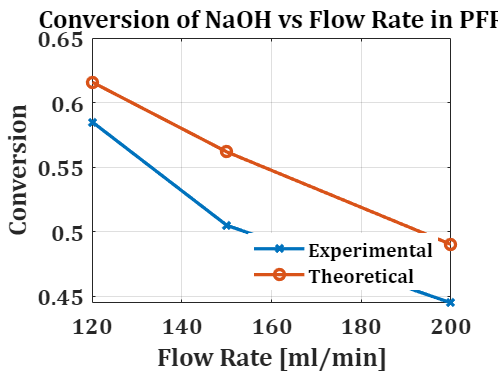

plot(NaOH_flow,X_exp_PFR,'-x',LineWidth=2);hold on;
title('Conversion of NaOH vs Flow Rate in PFR')
ylabel('Conversion')
xlabel('Flow Rate [ml/min]')
grid on;
plot(NaOH_flow,X_th_PFR,'-o',LineWidth=2);
set(gca,'FontSize',14,'FontWeight','bold','FontName','Cambria')
legend({'Experimental',"Theoretical"},'Location','southeast','FontSize',12,'FontWeight','bold','EdgeColor',[1 1 1])
hold off;

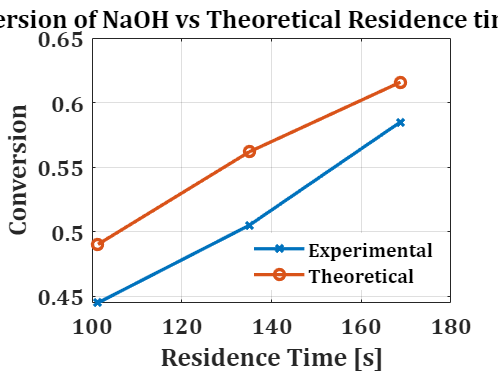


plot(tau_PFR,X_exp_PFR,'-x',LineWidth=2);hold on;
title('Conversion of NaOH vs Theoretical Residence time in PFR')
ylabel('Conversion')
xlabel('Residence Time [s]')
grid on;
plot(tau_PFR,X_th_PFR,'-o',LineWidth=2);
set(gca,'FontSize',14,'FontWeight','bold','FontName','Cambria')
legend({'Experimental',"Theoretical"},'Location','southeast','FontSize',12,'FontWeight','bold','EdgeColor',[1 1 1])
hold off;

Plots for CSTR

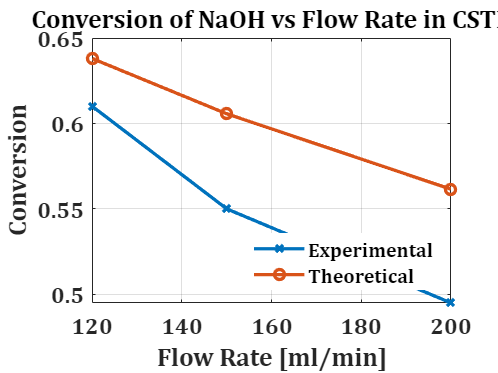

plot(NaOH_flow,X_exp_CSTR,'-x',LineWidth=2);hold on;
title('Conversion of NaOH vs Flow Rate in CSTR')
ylabel('Conversion')
xlabel('Flow Rate [ml/min]')
grid on;
plot(NaOH_flow,X_th_CSTR,'-o',LineWidth=2);
set(gca,'FontSize',14,'FontWeight','bold','FontName','Cambria')
legend({'Experimental',"Theoretical"},'Location','southeast','FontSize',12,'FontWeight','bold','EdgeColor',[1 1 1])
hold off;

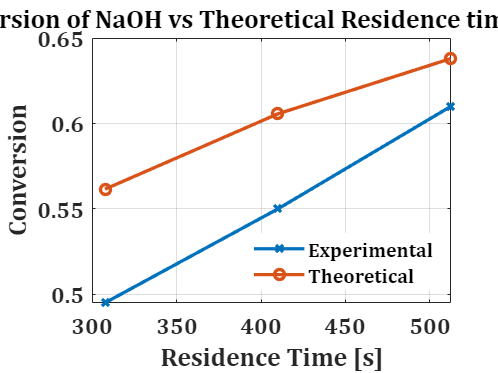


plot(tau_CSTR,X_exp_CSTR,'-x',LineWidth=2);hold on;
title('Conversion of NaOH vs Theoretical Residence time in CSTR')
ylabel('Conversion')
xlabel('Residence Time [s]')
grid on;
plot(tau_CSTR,X_th_CSTR,'-o',LineWidth=2);
set(gca,'FontSize',14,'FontWeight','bold','FontName','Cambria')
legend({'Experimental',"Theoretical"},'Location','southeast','FontSize',12,'FontWeight','bold','EdgeColor',[1 1 1])
hold off;

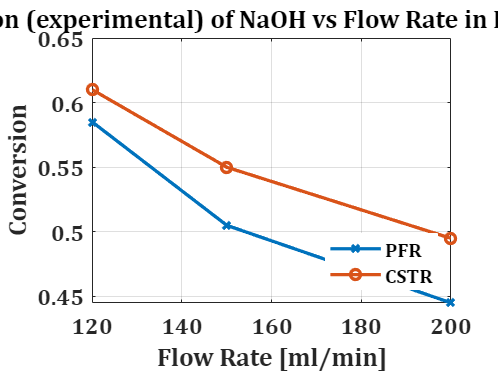


% MIX PLOT
plot(NaOH_flow,X_exp_PFR,'-x',LineWidth=2);hold on;
title('Conversion (experimental) of NaOH vs Flow Rate in PFR and CSTR')
ylabel('Conversion')
xlabel('Flow Rate [ml/min]')
grid on;
plot(NaOH_flow,X_exp_CSTR,'-o',LineWidth=2);
set(gca,'FontSize',14,'FontWeight','bold','FontName','Cambria')
legend({'PFR',"CSTR"},'Location','southeast','FontSize',12,'FontWeight','bold','EdgeColor',[1 1 1])
hold off;

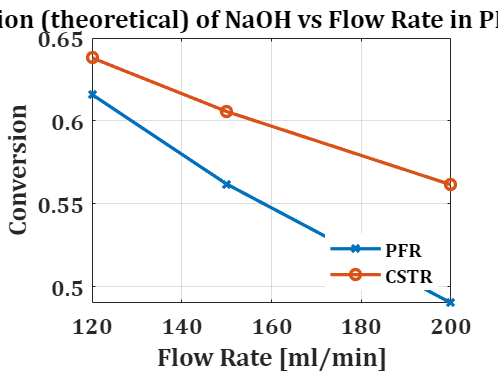


plot(NaOH_flow,X_th_PFR,'-x',LineWidth=2);hold on;
title('Conversion (theoretical) of NaOH vs Flow Rate in PFR and CSTR')
ylabel('Conversion')
xlabel('Flow Rate [ml/min]')
grid on;
plot(NaOH_flow,X_th_CSTR,'-o',LineWidth=2);
set(gca,'FontSize',14,'FontWeight','bold','FontName','Cambria')
legend({'PFR',"CSTR"},'Location','southeast','FontSize',12,'FontWeight','bold','EdgeColor',[1 1 1])
hold off;